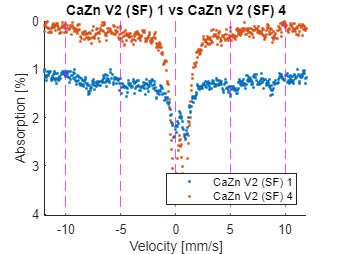

%clear crap
clear all
clf

%importing data
% data_1 = readtable("Year 3/Mossbauer/2301031507_SLS1.csv");
% data_4 = readtable("Year 3/Mossbauer/2303241302_SLS_4_diluted.csv");
% a = "SLS 1";
% b = "SLS 4";
% data_1 = readtable("Year 3/Mossbauer/2301191233_NBS1.csv");
% data_4 = readtable("Year 3/Mossbauer/2303161707_NBS_4_diluted.csv");
% a = "NBS 1";
% b = "NBS 4";
data_1 = readtable("Year 3/Mossbauer/2302200928_CaZnV2_1.csv");
data_4 = readtable("Year 3/Mossbauer/2303082139_CaZnV2_4_diluted.csv");
a = "CaZn V2 (SF) 1";
b = "CaZn V2 (SF) 4";

%%data_1
%calculating percentage absorption
max_y = max(table2array(data_1(:,2))); %extracting max y value for perc. absorbed calc
data_1.Var3=zeros(height(data_1),1);
%calculating perc absorption
for i = 1:1:height(data_1)
    data_1(i,3) = array2table(100*(max_y - table2array(data_1(i,2)))/max_y);
end

%adding y shift.
% (This is optional but splits out the two graphs if they overlap too much)
for i = 1:1:height(data_1)
    data_1(i,3) = array2table(table2array(data_1(i,3)) + 1);
end

%%data_4
%calculating percentage absorption
max_y = max(table2array(data_4(:,2))); %extracting max y value for perc. absorbed calc
data_4.Var3=zeros(height(data_4),1);
%calculating perc absorption
for i = 1:1:height(data_4)
    data_4(i,3) = array2table(100*(max_y - table2array(data_4(i,2)))/max_y);
end

%extracting x & y data
data_1_x = table2array(data_1(:,1));
data_1_y = table2array(data_1(:,3));
data_4_x = table2array(data_4(:,1));
data_4_y = table2array(data_4(:,3));

%plotting data
plot(data_1_x,data_1_y,".")
hold on %plotting on same graph
plot(data_4_x,data_4_y,".")

%setting limits
xlim([-12 12])

%statement to check largest absorption
if max(table2array(data_1(:,3))) > max(table2array(data_4(:,3)))
    ylim([0 max(table2array(data_1(:,3)))*1.1]) %10 percent of Max absorption
else
    ylim([0 max(table2array(data_4(:,3)))*1.1]) %10 percent of Max absorption
end

%adding x lines
xline(-10,"m--")
xline(-5,"m--")
xline(0,"m--")
xline(5,"m--")
xline(10,"m--")

%beautifying curve
ax = gca;
box off;
set(gca, 'YDir','reverse') %inverting y axis

%labelling graph
title(a + " vs " + b)
xlabel("Velocity [mm/s]");
ylabel("Absorption [%]");
legend(a,b,"Location","SouthEast")



hold off %end of plotting